## **Assignment2: **Spectrum Plots              

## **Kunanon Wanyen 66010103**

**1. Calculate and Plot Magnitude and Phase of Frequency Response, 𝐻(𝜔) of the following LCCDE :**

**    y[n] = 1.5y[n-1] - 0.85y[n-2] + x[n]**

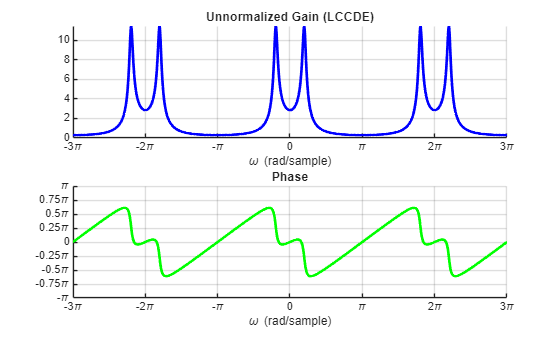

clc;
w = linspace(-3*pi, 3*pi, 1001);
% from y[n] = 1.5y[n-1] - 0.85y[n-2] + x[n]
%b = 1;
%a = [1 -1.5 0.85];
%H = freqz(b, a, w);
H = 1 ./ (1 - 1.5*exp(-1i*w) + 0.85*exp(-1i*2*w));

xt = [-3*pi -2*pi -pi 0 pi 2*pi 3*pi];
xl = {'-3\pi','-2\pi','-\pi','0','\pi','2\pi','3\pi'};
yt = [-pi -0.75*pi -0.5*pi -0.25*pi 0 0.25*pi 0.5*pi 0.75*pi pi];
yl = {'-\pi','-0.75\pi','-0.5\pi','-0.25\pi','0','0.25\pi','0.5\pi','0.75\pi','\pi'};

figure(1)
% Magnitude
A = subplot(2,1,1);
line(w, abs(H), 'Color', 'b', 'LineWidth', 2);
set(A, 'XLim', [w(1) w(end)]);
xlabel('\omega (rad/sample)')
title('Unnormalized Gain (LCCDE)')
grid on
xticks(xt); xticklabels(xl);

% Phase
A = subplot(2,1,2);
line(w, angle(H), 'Color', 'g', 'LineWidth', 2);
set(A, 'XLim', [w(1) w(end)], 'YLim', [-pi pi]);
xlabel('\omega (rad/sample)')
title('Phase')
grid on
xticks(xt); 
xticklabels(xl);
yticks(yt); 
yticklabels(yl);

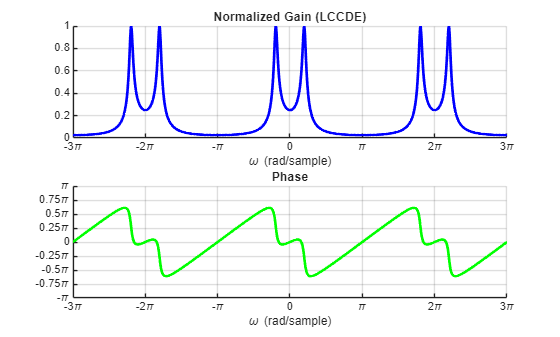


Nor_H = abs(H) / max(abs(H));
figure(2)
% Magnitude
A = subplot(2,1,1);
line(w, Nor_H, 'Color', 'b', 'LineWidth', 2);
set(A, 'XLim', [w(1) w(end)]);
xlabel('\omega (rad/sample)')
title('Normalized Gain (LCCDE)')
grid on
xticks(xt); 
xticklabels(xl);

% Phase
A = subplot(2,1,2);
line(w, angle(H), 'Color', 'g', 'LineWidth', 2);
set(A, 'XLim', [w(1) w(end)], 'YLim', [-pi pi]);
xlabel('\omega (rad/sample)')
title('Phase')
grid on
xticks(xt); 
xticklabels(xl);
yticks(yt); 
yticklabels(yl);

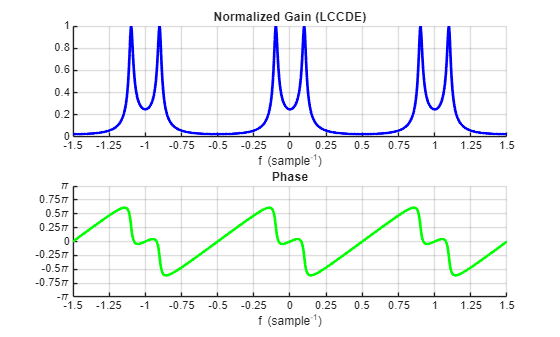


figure(3)
% Magnitude
A = subplot(2,1,1);
f = w ./ (2*pi);
line(f, Nor_H, 'Color', 'b', 'LineWidth', 2);
set(A, 'XLim', [f(1) f(end)]);
xlabel('f (sample^{-1})')
title('Normalized Gain (LCCDE)')
grid on
xticks([-1.5:0.25:1.5]);

% Phase
A = subplot(2,1,2);
line(f, angle(H), 'Color', 'g', 'LineWidth', 2);
set(A, 'XLim', [f(1) f(end)], 'YLim', [-pi pi]);
xlabel('f (sample^{-1})')
title('Phase')
grid on
xticks([-1.5:0.25:1.5]);
yticks(yt); 
yticklabels(yl);

**2. Calculate and Plot Magnitude and Phase of Frequency Response, 𝐻 𝜔 of the given Finite Impulse Response from Assignment1 (FIR.mat)**

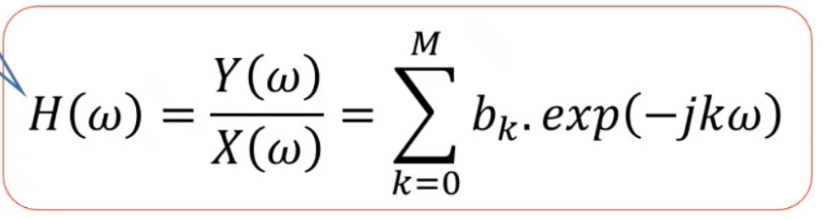

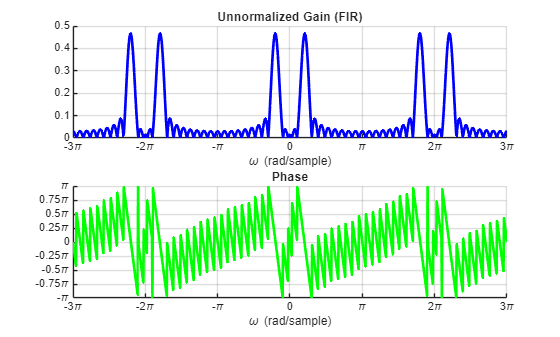

load("FIR.mat");
H_FIR = 0;
for n = 1:length(hn)
    H_FIR = H_FIR + hn(n) * exp(-1i*w*(n-1));
end

figure(4)
% Magnitude
A = subplot(2,1,1);
line(w, abs(H_FIR), 'Color', 'b', 'LineWidth', 2);
set(A, 'XLim', [w(1) w(end)]);
xlabel('\omega (rad/sample)')
title('Unnormalized Gain (FIR)')
grid on
xticks(xt); 
xticklabels(xl);

% Phase
A = subplot(2,1,2);
line(w, angle(H_FIR), 'Color', 'g', 'LineWidth', 2);
set(A, 'XLim', [w(1) w(end)], 'YLim', [-pi pi]);
xlabel('\omega (rad/sample)')
title('Phase')
grid on
xticks(xt); 
xticklabels(xl);
yticks(yt); 
yticklabels(yl);

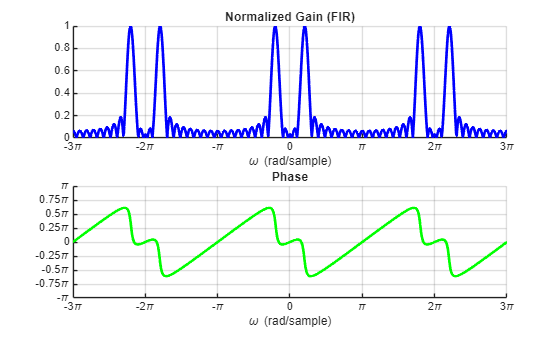


Nor_H_FIR = abs(H_FIR) / max(abs(H_FIR));
figure(5)
% Magnitude
A = subplot(2,1,1);
line(w, Nor_H_FIR, 'Color', 'b', 'LineWidth', 2);
set(A, 'XLim', [w(1) w(end)]);
xlabel('\omega (rad/sample)')
title('Normalized Gain (FIR)')
grid on
xticks(xt); 
xticklabels(xl);

% Phase
A = subplot(2,1,2);
line(w, angle(H), 'Color', 'g', 'LineWidth', 2);
set(A, 'XLim', [w(1) w(end)], 'YLim', [-pi pi]);
xlabel('\omega (rad/sample)')
title('Phase')
grid on
xticks(xt); 
xticklabels(xl);
yticks(yt); 
yticklabels(yl);

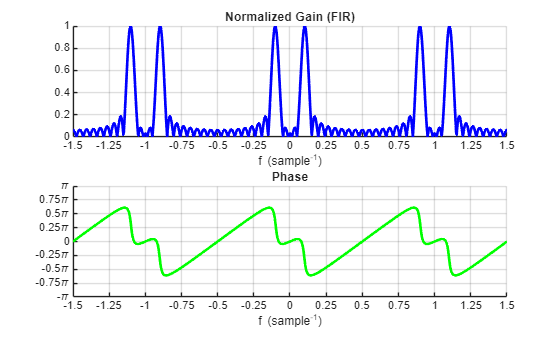


figure(6)
% Magnitude
A = subplot(2,1,1);
f = w ./ (2*pi);
line(f, Nor_H_FIR, 'Color', 'b', 'LineWidth', 2);
set(A, 'XLim', [f(1) f(end)]);
xlabel('f (sample^{-1})')
title('Normalized Gain (FIR)')
grid on
xticks([-1.5:0.25:1.5]);

% Phase
A = subplot(2,1,2);
line(f, angle(H), 'Color', 'g', 'LineWidth', 2);
set(A, 'XLim', [f(1) f(end)], 'YLim', [-pi pi]);
xlabel('f (sample^{-1})')
title('Phase')
grid on
xticks([-1.5:0.25:1.5]);
yticks(yt); 
yticklabels(yl);